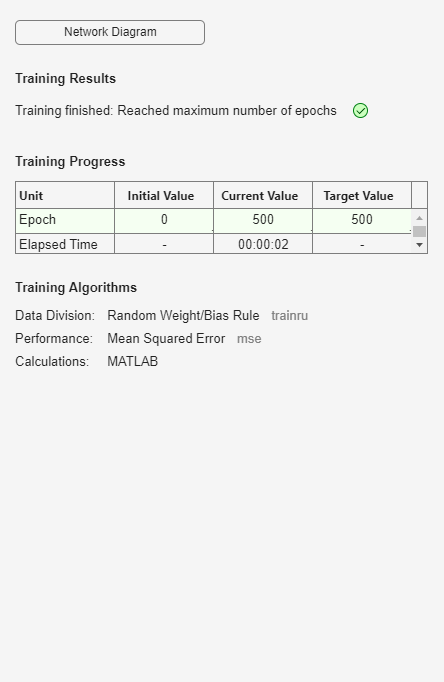

%福冈与城市分类（变量除以标准差）
clear                                       %清理内存
P=[14.1865 14.7286 15.5418 16.9876 16.1744 14.7286 14.6383 
2.8297 3.6757 4.1483 5.4669 4.9534 2.8472 4.3525 
6.9131 6.5251 5.4016 5.3484 5.7834 3.8775 6.2591 
-3.1628 -2.6561 -1.4586 -0.7523 -0.6909 -0.7062 -1.2590 
0.8319 1.2260 2.0142 3.5029 3.2840 2.4521 2.7148];
net=newc([-1 2;-1 2;-1 2;-1 2;-1 2],2);     %创建一个五变量二分类的竞争型网络
net.trainParam.epochs=500;                  %指定最大训练次数为
net=train(net,P);                           %训练网络

Y=sim(net,P)                                %仿真结果

Y =      0     0     1     1     1     0     1
     1     1     0     0     0     1     0


Yc=vec2ind(Y)                               %输出分类向量

Yc =      2     2     1     1     1     2     1
